clc, clear
N = 1e3;
a = strings(N,3);

s = serialport("COM7",57600);
configureTerminator(s,"CR/LF");
for i = 1:N
    a(i,:) = strsplit(readline(s));
end
b = double(a);
clear s


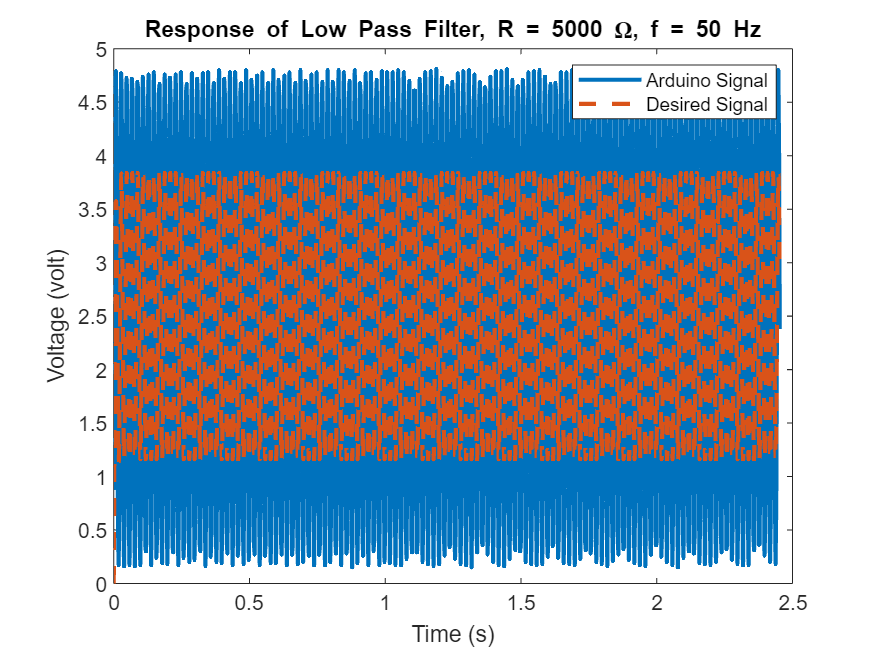

syms s t
plot((b(:,1))/1e4,b(:,2),'LineWidth',2)
hold on
f = 50;
y = 2.5*sin(2*pi*f*t)+2.5;
G_s = laplace(y);
R = 5000;
C = 1e-6;
G_filter = 1/(1 + R*C*s);
f = vpa(ilaplace(G_filter*G_s,t));
tt = 0 : 0.001 : 2.4527;
plot(tt,subs(f,t,tt),'--','LineWidth',2)
xlabel('Time (s)')
ylabel('Voltage (volt)')
title('Response of Low Pass Filter, R = 5000 \Omega, f = 50 Hz');
legend('Arduino Signal','Desired Signal')